# Worksheet 1: Bike Share

#### Due Friday, September 18

Welcome to your first ModSim worksheet! We call them worksheets because, in the olden days (circa 2019), we used to hand them out in the studios, and students would write on them with graphite- or other pigment-based implements. Our goal this year is to adapt the worksheet learning experience to the online format of the course, without losing what we see as its essential elements. These elements include:

- *Work at your own pace.* There are three main parts to this worksheet (plus the reading questions and reflections), and you have three class sessions to complete it. We expect that many students will be able to complete approximately one part per day, with minimal outside work beyond reading the assigned chapters of the Robot Book. That said, you are welcome to work ahead and/or take time after class to finish parts that you don't complete in class, possibly with help a course assistant (CA). There are also some more challenging optional activities at the end of the worksheet if you'd like to go further.

- *Collaborate with your peers.* As in the past, we will ask you to work in randomly assigned studio groups. This year, the groups will consist of 4-5 students. You will work with the same group for the duration of the worksheet. Each group will have a breakout room associated with their Zoom studio, emulating the experience of working at a physical table. We encourage you to collaborate closely and discuss each section together. However, each of you will complete and submit an individual copy of the worksheet.

- *Learn by doing.* The worksheets are designed to give you practice with the concepts and skills you will need for the projects in the course. They complement the readings from the Robot Book, as well as the full-class "auditorium" sessions. If you are able to do the things we ask you to do in the worksheets, you will probably be in good shape for the projects. (And conversely, if you find yourself struggling with the worksheets, you should take the initiative to seek help because we will expect you to be able to do these things in your project work.)

Each worksheet will begin with a set of learning objectives and end with a set of reflection questions to help you deepen your understanding and direct your own learning. Information on assignment submission and assessment can be found on Canvas.

### Learning Objectives

After completing this worksheet, you should be able to:

- Describe the key concepts from Chapters 1-4 (including modeling, simulation, scripts, and debugging), and explain how they relate to each other.

- For a simple model like that of the bike sharing system presented in Chapters 2 and 3, create scripts that (a) update the state of the model for a single time step; (b) simulate the model by running the update script in a loop; and (c) plot the results as a time series (labeling the axes appropriately).

- Modify the implementation of a model to use parameters stored in global variables, and to store the results as vectors.

- Perform a one-parameter sweep of a model, plotting the results on a single graph as a set of time series (labeled appropriately with a legend).

- Reduce the results of a simulation run to a single value (e.g., the final value of a state variable), and perform a two-parameter sweep of a model, plotting the results on a single graph as a set of parameter series (labeled appropriately with a legend).

## 1. Reading Questions

Please read chapters 1–4 of the Robot Book, then answer the following questions.

(Here and in the rest of the worksheet, each question or prompt that asks for a response is numbered. You should replace each "% Your text here" or "% Your code here" placeholder with your response.)

1.1. What is a model? How does modeling relate to simulation?

(Note that the term *simulation* is not defined in the book. [Wikipedia](https://en.wikipedia.org/wiki/Simulation) says, "A simulation is an approximate imitation of ... a process or system that represents its operation over time." That definition is good enough for us!)

**Response:**

A model is a simplified representation of a real-world system used to make predictions. A simulation is a type of model.

1.2. Describe at least two different ways of modeling the fall of a penny from the top of the Empire State Building. How do your models differ? Which (if any) is more useful for answering the question, "How much would it hurt to get hit by a penny that was dropped off the top of the Empire State Building?"

**Response:**

- Simply model the penny as an infinitely flat disk that remains entirely parallel to the ground at all times.

- Model the penny as a very short 3D cylinder that rotates as it falls, resulting in variable air resistance.

1.3. What is a MATLAB script, and why might you want to write one?

**Response:**

A MATLAB script is a text file that contains MATLAB code, enabling you to run your code over and over again without retyping it each time. This is useful because as programs get more complex, you wouldn't want to take the time to type it out over and over again (and if you did, you'd almost certainly make lots of mistakes in the process).

1.4. The first three chapters of the book introduce six "theorems of debugging" (there are eight in total; the seventh and eighth are in Chapters 7 and 8, respectively). What does debugging have to do with modeling and simulation? Can you give an example of "debugging" from your previous experience, whether or not in a programming context? 

**Response:**

When we build our models/simulations as computer programs (for example, in MATLAB), then--just like any other program--we need to make sure it works properly (ie. has no bugs). Debugging is the process of removing the bugs. I've debugged many different programs before, I don't have a precise example off the top of my head.

1.5. In Chapter 1 (p. 3), Allen advocates "iterative modeling." In Chapter 3 (pp. 30-31), he advocates "incremental development." What do these approaches have in common? Do you agree with his advice? Why do you think ModSim students often fail to follow it?

**Response:**

Both iterative modeling and incremental development start off as simple as possible, slowly adding complexity while validating those changes each time. It's absolutely a good approach, but ModSim students fail to follow it because it's not as fun and requires lots of discipline and patience.

## 2. A First-Cut Model

This section of the worksheet closely follows the treatment of the bike share system in the Robot Book. By completing the exercises related to this system in Chapters 2 and 3, you will implement a simple model of bicycle movement between two stations (in Boston and Cambridge), simulate the model for a time period of one month, plot the results, and interpret them.

### Storing and Updating the State of the System

2.1. Work through Chapter 2, Exercise 2 to create a script called `bike_update` that updates the number of bikes in each location (Boston and Cambridge) from one day to the next. Test it here by setting the number of bikes in both locations to 100, then running the update script. How many bikes are in each location after one update step?

**Response:**

b = 100

b = 100

c = 100

c = 100

bike_update
b

b = 98

c

c = 102

### Simulating a Month of the Bike Sharing System

2.2. Work through Chapter 3, Exercise 1 to create a script called `bike_loop` that uses a `for` loop to run `bike_update` 30 times. As in the exercise above, start with 100 bikes in each location. Test the script here.

**Response:**

b = 100

b = 100

c = 100

c = 100

for i=1:30
    bike_update
end
b

b = 83

c

c = 117

2.3. What happened? Why?

**Response:**

Because more bikes go from Boston to Cambridge every day than the reverse, Cambridge ends up with more than its fair share of bikes after the end of the month.

### Plotting the State of the System over Time

2.4. If your `bike_update` script displays the values of `b` and `c`, modify it so that it no longer does so; call the modified script `bike_update2`. Then work through Chapter 3, Exercise 2. Call the modified looping script `bike_loop2`; it should only display a graph as output. Test it here.

**Response:**

b = 100

b = 100

c = 100

c = 100

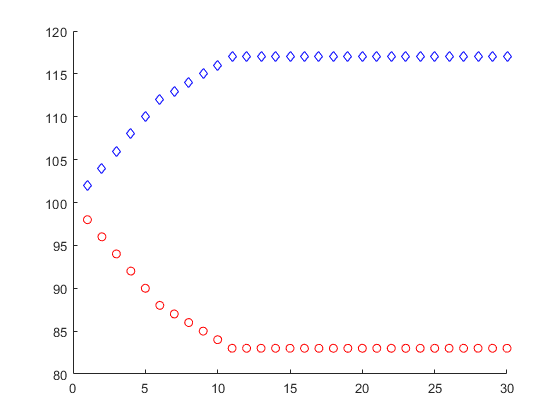


clf
hold on
for i=1:30
    bike_update
    plot(i, b, "ro")
    plot(i, c, "bd")
end
hold off

Congratulations — if you produced a figure that looks like this, you've successfully completed this part!

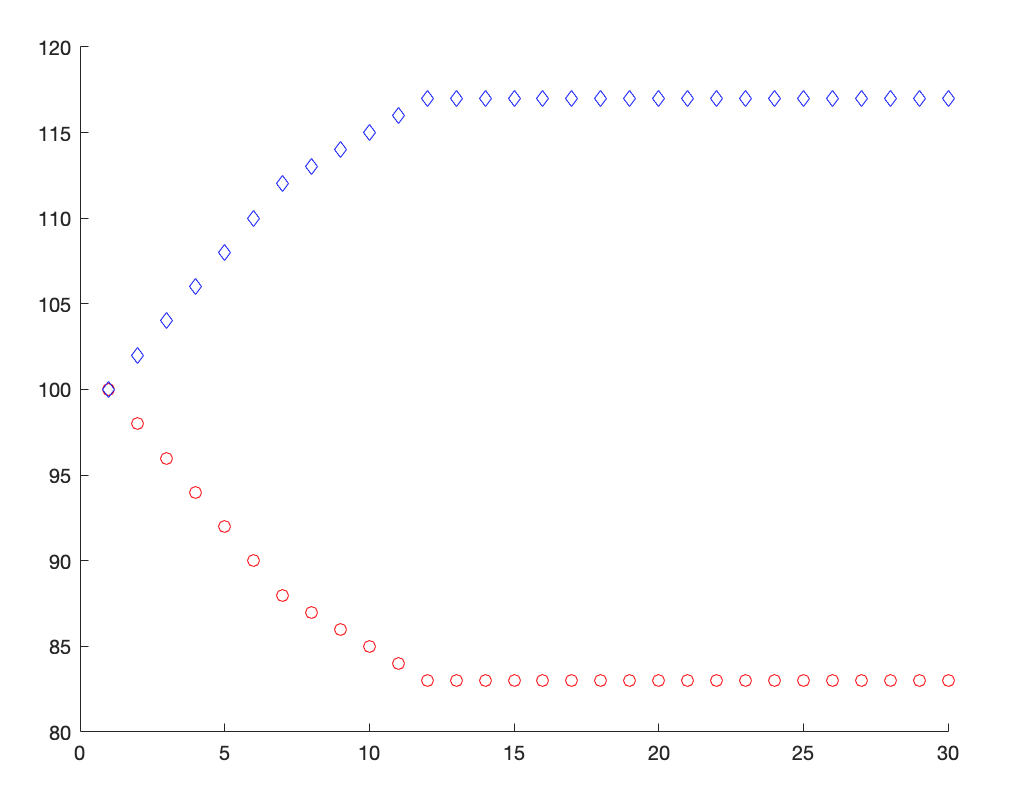bike_loop3

## 3. Sweeping Parameters

In this section of the worksheet, we'll go beyond the treatment of the bike share model in the book to develop some ideas that will play important roles in the rest of the course. In particular, we'll revisit the idea of parameter sweeping that Zach introduced us to at the end of the Day 2 notebook on falling pennies, which is important because you'll almost always want to run a simulation multiple times to explore how it behaves for different parameter values.

### Parameters and Results

Before we dive into parameter sweeping, we need to start thinking more clearly about how the parameters and results of our bike share model are stored and manipulated in our scripts.

3.1. What are the parameters of the bike share model? Where are they defined in the scripts you've written so far?

**Response:**

Bikes in Boston (b, global variable), Bikes in Cambridge (c, global variable), % of bikes that go from Boston to Cambridge daily (magic number in bike_update), % of bikes that go from Cambridge to Boston daily (magic number in bike_update)

3.2. What results are generated by a single simulation run of the bike share model? What did we do with them in the scripts you've written so far?

**Response:**

The number of bikes in Boston and the number of bikes in Cambridge. We plot them one by one.

3.3. Now create a script called `bike_update3` that uses variables called `b_frac` and `c_frac` to represent the fraction of bikes in Boston and Cambridge (respectively) that move on a given day. Then create `bike_loop3` to call `bike_update3` repeatedly and store the results in vectors called `B` and `C` instead of plotting the state of the system inside the loop. In your response below, call `bike_loop3` and plot the results using one `plot` statement for each vector, replicating the figure you generated at the end of Part 1 above.

**Response:**


b_to_c_frac = 0.05

b_to_c_frac = 0.0500

c_to_b_frac = 0.03

c_to_b_frac = 0.0300

bike_loop;

clf
hold on;
plot(B, "ro")
plot(C, "bd")
hold off

Now let's add some labels. If your code above generates a plot, this code should label it correctly:

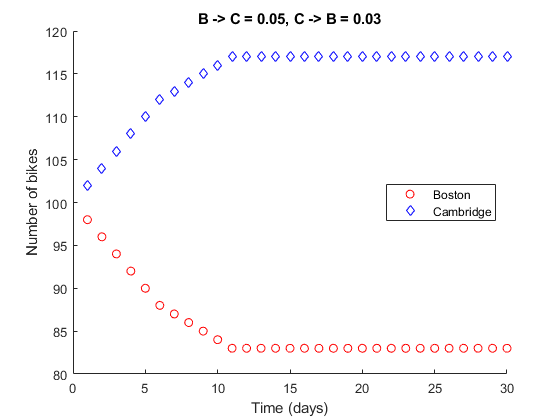

xlabel('Time (days)')
ylabel('Number of bikes')

title(['B -> C = ', num2str(b_to_c_frac), ', C -> B = ', num2str(c_to_b_frac)])
legend('Boston', 'Cambridge', 'Location', 'east');

(You should run the code above, which should generate a nicely labeled plot.)

3.4. Okay, so you've successfully reproduced the same plot you generated in the last part of the worksheet. What's different this time, and why is it better?

**Response:**

This version is cleaner because the concerns are properly seperated: the logic that deals with computation (bike_update, etc.) only deals with computation, and the logic that deals with graphing only deals with graphing. That makes each part simpler and easier to deal with. However, with (very) large datasets, this approach could have different performance characteristics that may be undesirable

### Sweeping One Parameter

3.5. Create a script called `bike_sweep_plot` to sweep `b_frac` from 0.01 to 0.07 (in increments of 0.01), and plot the results as a set of time series that are overlaid on the same graph. Hold `c_frac` at 0.03, as in the previous simulations.

*Hint — this code creates a range of values from 1 to 3 in increments of 0.5:*

1:0.5:3

ans =     1.0000    1.5000    2.0000    2.5000    3.0000


**Response:**

c_to_b_frac = 0.03

c_to_b_frac = 0.0300

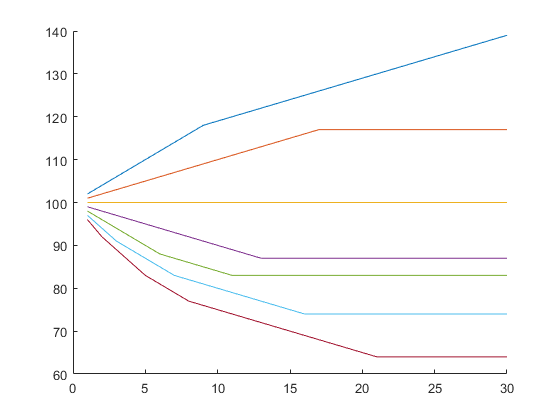

bike_sweep

clf;
hold on;
plot(transpose(Bs));
hold off;

Once again, let's add some labels. (We are not expecting you to be able to write this code, but you should be able to figure out what it does and modify it appropriately.)

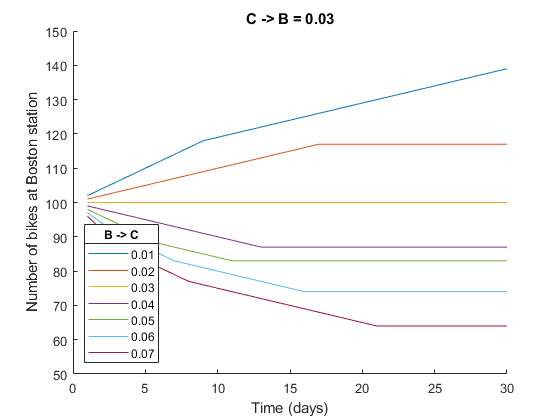

xlabel('Time (days)')
ylabel('Number of bikes at Boston station')
xlim([0 30])      % x-axis limits (specified as a two-element vector)
ylim([50 150])    % y-axis limits (specified as a two-element vector)

title(['C -> B = ', num2str(c_to_b_frac)])

lgd = legend(string(b_to_c_frac_sweep));  % need to use string(...) to convert
                                     % b_frac_range into a string array
                                     
lgd.Title.String = 'B -> C';        % need to use \_ to get an underscore
lgd.Location = 'southwest';          % (otherwise _ is interpreted as a subscript)

(Again, please run the code above to generate a nicely labeled plot.)

### Sweeping Two Parameters

3.6. Create a script called `bike_sweep_reduce` to sweep `b_frac` from 0.01 to 0.07, storing the final value of each simulation run in a vector called `B_end`. Run this script for a range of `c_frac` parameter values (also from 0.01 to 0.07), and plot the results as a set of parameter series that are overlaid on the same graph. This time, you create the axis labels and legend!

**Response:**

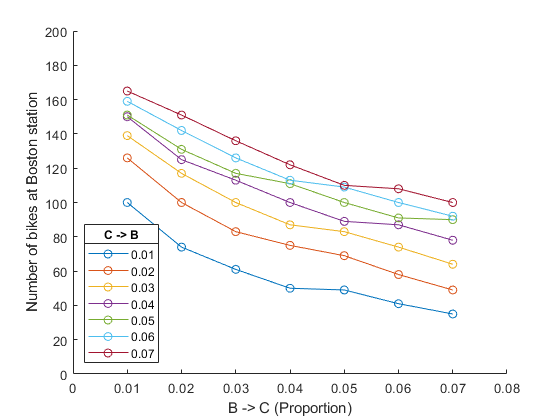

c_to_b_frac_sweep = 0.01:0.01:0.07;
b_to_c_frac_sweep = 0.01:0.01:0.07; % TODO: Keep in sync with b_to_c_frac_sweep in bike_sweep (ideally, they would be the same variable.)

clf;
hold on;

final_Bs = zeros(size(c_to_b_frac_sweep, 2), size(b_to_c_frac_sweep, 2));

c_to_b_sweep_i = 1;
for c_to_b_frac=c_to_b_frac_sweep
    bike_sweep
    plot(b_to_c_frac_sweep, transpose(Bs(:, end)), "o-");
    c_to_b_sweep_i = c_to_b_sweep_i + 1;
end


xlabel('B -> C (Proportion)')
ylabel('Number of bikes at Boston station')
xlim([0 0.08])      % x-axis limits (specified as a two-element vector)
ylim([0 200])    % y-axis limits (specified as a two-element vector)

lgd = legend(string(b_to_c_frac_sweep));  % need to use string(...) to convert
                                     % b_frac_range into a string array
                                     
lgd.Title.String = 'C -> B';        % need to use \_ to get an underscore
lgd.Location = 'southwest';          % (otherwise _ is interpreted as a subscript)

## 4. Evaluating and Improving the Model

Whenever we ask you to create a model, we're also going to ask you to interpret and evaluate it. For each of the three projects in the course, you'll also have an opportunity to improve your model based on feedback from your studio instructor and CAs. In this part of the worksheet, we invite you to practice this process in the context of the bike share model you worked with this week.

4.1. What is your assessment of the bike share model? Are there ways in which it is a "good" model of a bike share system, or at least a useful starting point for one? In what ways is it a "bad" model? To what extent do you think these flaws or limitations can be overcome through iterative modeling / incremental development, versus starting again from scratch?

**Response:**

I think the answer to this depends on the level of precision required in the final model. I think this model is probably a decent (starting place for a) relatively simple bikeshare model, but I don't know if it could be turned into a fully-fledged detailed bike model. In particular, I think the core assumption that the number of bikes crossing the Charles is proportional to the number of bikes on either side of it is good enough at a high level, but is likely not true on thorough examination: when an individual approaches the bikeshare station, the number of bikes available has zero impact on where they go. Additionally, there's currenly no recognition of the varying traffic patterns of humans (ex. weekends, summers, pandemics, weather, etc.), or of the non-ideal nature of bikes as a physical object (that gets stolen, broken, lost, vandalized, dirty, etc.) in the model, which would substantially effect the result.

In terms of implementation, I think the model needs a thorough rewrite using (at a minimum) functions. Right now, we're using the tried-and-true programming strategy of "all variables are global," and it's immensely confusing and frusturating. It makes the model hard to work on and makes me concerned there's a subtle bug somewhere I'm not catching as a result of shadowing or something. Additionally, our current model is hard-coded to have exactly two bikeshare stations. Since no real bikeshare system has only two stations, we'd need to re-write it to support an arbitrary number, preferably with each station nicely encapsulated in an object of some sort.

4.2 Of the many possible ways to improve the bike share model, which would you prioritize for your *next* iteration, and why? In what ways would your changes yield a better model? Do you see any possible risks or downsides?

**Response:**

Honestly, I'd probably start with the refactoring/re-writing, for two reasons: first, having better encapsulation would make me more confident that the code is doing what I think it's doing, and second, it would be an important first step in making more complex improvements to the model later on. 

## 5. Reflection Questions

The purpose of this final section is to give you an opportunity to reflect on your experience in completing the worksheet. This information may be helpful for your studio instructor, but it is mainly intended to be helpful to you.

5.1. What was the most challenging part of this worksheet for you? Did you get stuck at any point along the way? If so, what strategies did you employ to get unstuck, and how did they work?

**Response:**

The MATLAB ideosyncracies were definately the hardest part for me. I come from a programming backgound, and MATLAB does things differently than many (all?) of the other languages I've used, which takes some getting used to. I don't recall getting significantly stuck at any point.

5.2. How did the "virtual studio table" experience work for you? To what extent were you able to seek and receive help from your peers? What are some things you can do next week to make these interactions more effective for your learning? What are some things the instructors or CAs can do?

**Response:**

The virtual studio table was really nice because it gave you an option when you were stuck on something small to get a quick clarification without having to go find a CA or whatever. I think more-regular "I'm good, you good?" check-ins with the table, instead of just when someone is stuck, would be good.